# Machine Learning From Coursera

Exercise 2 -Classification

data=load("ex2data1.txt");
x=data(:,[1,2]);
y=data(:,3);
fprintf("First 5 examples of data:\n");

First 5 examples of data:


fprintf("x=[%.0f %.0f],y=[%.f]\n",[x(1:5,:) y(1:5,:)]');

x=[35 78],y=[0]
x=[30 44],y=[0]
x=[36 73],y=[0]
x=[60 86],y=[1]
x=[79 75],y=[1]


We have to make a classification model based on the data. First, we plot the available data.We then find out the cost and gradient value to train the model. The value of cost will have to decrease on every iterations. Finally, we predict on new examples whether to know in which class of our example exists.

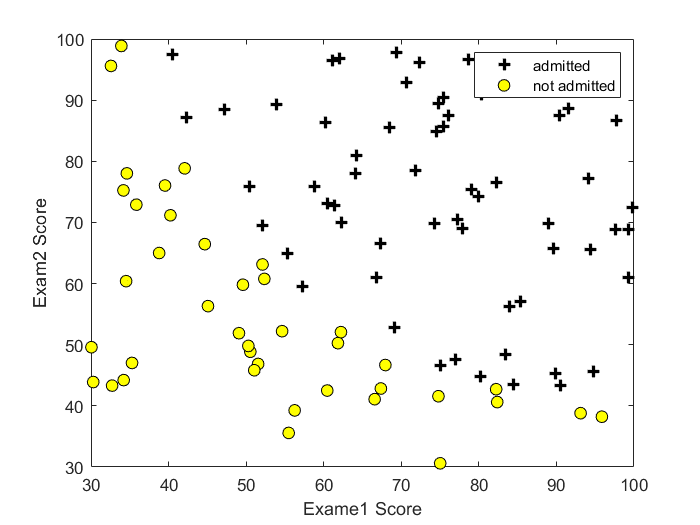

%plot the data
pos=find(y==1);neg=find(y==0);
plot(x(pos,1),x(pos,2),'k+','LineWidth',2,'MarkerSize',7);
hold on
plot(x(neg,1),x(neg,2),'ko','MarkerFaceColor','y','MarkerSize',7);
hold off
xlabel('Exame1 Score');
ylabel('Exam2 Score');
legend('admitted','not admitted');

%in this section we will prepare the data for training
[m,n]=size(x);
theta=zeros(n+1,1); %initialize theta 
X=[ones(m,1),x];
%calling the cost and gradient funtion
[J,Gradient]=cost_gradient(theta,X,y,m);
fprintf("Cost at Initial Theta: J= %.3f",J);

Cost at Initial Theta: J= 0.693

test_theta=[-24; 0.2; 0.2];
[J]=cost_gradient(test_theta,X,y,m);
fprintf("Cost at tested Theta: J= %.3f",J);

Cost at tested Theta: J= 0.218

## Optimizing with fminunc

%set options for fminunc
options = optimset('GradObj', 'on', 'MaxIter', 400);
[theta, cost] = fminunc(@(t)(costFunction(t, X, y)), initial_theta, options);


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


fprintf('Cost at theta found by fminunc: %.3f\n', cost);

Cost at theta found by fminunc: 0.203


fprintf('Theta: \n');

Theta: 


fprintf(' %.3f \n', theta);

 -25.161 
 0.206 
 0.201 


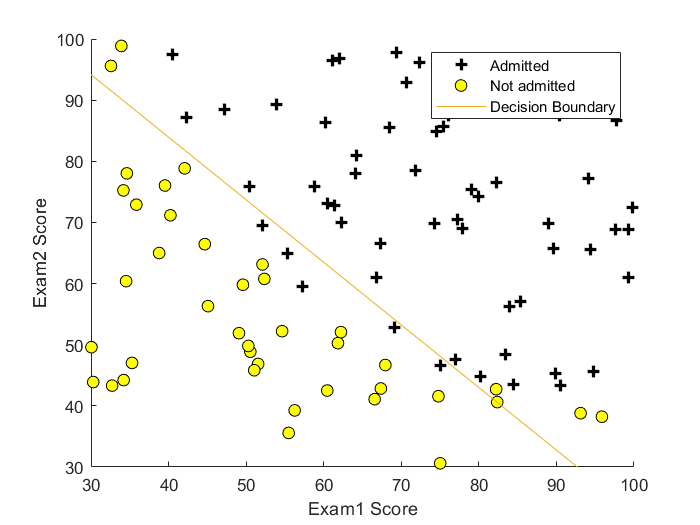

plotDecisionBoundary(theta,X,y)

Decision Boundary of Logistic Regression is the set of all points x that satisfy:

P(y=1|x)=P(y=0|x)=1/2

Given: $P\left(y=1\left|x\right.\right)$=$\frac{1}{1+e^{-\theta^t X} }$     where $\theta =\left(\theta_0 +\theta_1 +\ldotp \ldotp \ldotp \theta_{n+1} \right)$and $x=\left(1,x_1 ,x_2 ,\ldotp \ldotp \ldotp ,x_n \right)$


$$\frac{1}{1+e^{{-\theta }^t X} }=\frac{1}{2}$$



$$\theta^{-T} X=0$$


$\left(\theta_0 +\theta_1 x_1 +\theta_{n+1} x_n \right)$=0

For two dimensional data,

$\left(\theta_0 +\theta_1 x_1 +\theta_2 x_2 \right)$=0


$$x_1 =-\frac{\theta_0 }{\theta_1 }-\frac{\theta_2 }{\theta_1 }x_2 \;;$$
 
$$x_1 =-\frac{\theta_0 }{\theta_1 }-\frac{\theta_2 }{\theta_1 }x_2$$


In matlab, $\theta \;\textrm{starts}\;\textrm{from}\;1$, so $x_1 =-\frac{\theta_1 }{\theta_2 }-\frac{\theta_3 }{\theta_2 }x_2 \;;$ $x_1 =-\frac{\theta_1 }{\theta_2 }-\frac{\theta_3 }{\theta_2 }x_2$

## Prediction and Accuracies on Unseen data

Testing a new data: Exam1 Score=45, Exam2 Score=85

prob=sigmoid([1 45 85]*theta);
fprintf(['For a student with scores 45 and 85, we predict an admission ' ...
         'probability of %.2f '], prob);

For a student with scores 45 and 85, we predict an admission probability of 0.78 

% to computer accuracy on our training set
 p=Predict(theta,X);
 fprintf("Accuracy on our training set: %.f",mean(double(p==y))*100);

Accuracy on our training set: 89

function plotDecisionBoundary(theta, X, y)
plotData(X(:,2:3), y);
hold on
if size(X, 2) <= 3
    % Only need 2 points to define a line, so choose two endpoints
    plot_x = [min(X(:,2))-2,  max(X(:,2))+2];

    % Calculate the decision boundary line
    plot_y = (-1./theta(3)).*(theta(2).*plot_x + theta(1));

    % Plot, and adjust axes for better viewing
    plot(plot_x, plot_y)    
    % Legend, specific for the exercise
    legend('Admitted', 'Not admitted', 'Decision Boundary')
    axis([30, 100, 30, 100])
else
    % Here is the grid range
    u = linspace(-1, 1.5, 50);
    v = linspace(-1, 1.5, 50);
    z = zeros(length(u), length(v));
    % Evaluate z = theta*x over the grid
    for i = 1:length(u)
        for j = 1:length(v)
            z(i,j) = mapFeature(u(i), v(j))*theta;
        end
    end
    z = z'; % important to transpose z before calling contour

    % Plot z = 0
    % Notice you need to specify the range [0, 0]
    contour(u, v, z, [0, 0], 'LineWidth', 2)
end
hold off
end
function s=sigmoid(z)
s=zeros(size(z));
s=1./(1+exp(-z));
end
function [J,Gradient]=cost_gradient(theta,X,y,m)
h=sigmoid(X*theta);
J=(1/m)*sum(-y.*log(h)-(1-y).*log(1-h));
Gradient=zeros(size(theta,1),1);
for i=1:size(Gradient)
    Gradient(i)=(1/m)*sum((h-y).*X(:,i));
end
end
function [predict]=Predict(theta,X)
 m=size(X,1);
 predict=zeros(m,1);
 predict=round(sigmoid(X*theta));
 end       
